model = load("FasterRcnnDetector.mat");
load("allData.mat");
[~,testData] = splitData(allData,0.8);

testData = testData(1,:);

imds = imageDatastore(testData.imgName);
blds = boxLabelDatastore(testData(:,2));

results = detect(model.detector, imds);

[ap, recall, precision] = evaluateDetectionPrecision(results, blds);

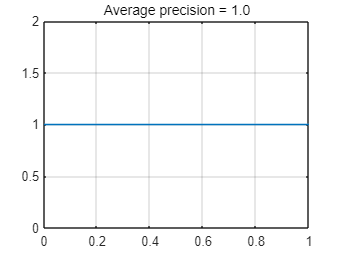

figure;
plot(recall, precision);
grid on
title(sprintf('Average precision = %.1f', ap))

[numOfImg,~] = size(testData.imgName);
str = testData.imgName(1,:);
img = imread(str);

result = detect(model.detector,img);
real = testData.bbox{1};

area = rectint(result, real);
union = prod(result(3:4)) + prod(real(3:4)) - area;
iou = area/union;